Check if a homogenous layout is sensitive to differences in timestep.

This is a simple layout, with unmodified S cerevisiae growing in a medium with 10mmol glucose.

Uses the data file **timestep_sensitivity_glc_biodata.mat**

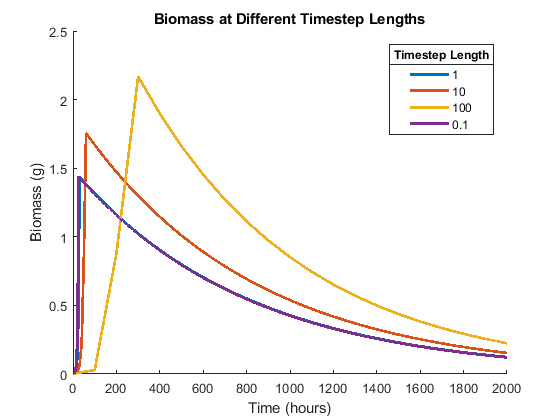

colors = lines();
figure();
hold on;
timesteps = [0 0 0 0];
for i = 1:4
    timestep = 2000 / max(biodat{i}.t);
    timesteps(i) = timestep;
    plot(timestep * biodat{i}.t,biodat{i}.biomass,'color',colors(i,:),'LineWidth',2,...
        'DisplayName',num2str(timestep));
end
leg = legend();
title(leg,'Timestep Length');
title('Biomass at Different Timestep Lengths');
xlabel('Time (hours)');
ylabel('Biomass (g)');
hold off;

### PART 2: 

Comparing timestep sensitivity in 2d sims

Data is saved as "timestep_sensitivity_2ddata.mat"

%prepare a bunch of layouts
l = load('C:\sync\biomes\models\yeastGEM_8.3.2.mat');
args.p6.v.maxspacebiomass = 1e8;
args.p6.v.enzdecayperhour = 0;
args.p6.v.drainatedges = false;
args.p6.v.maxcycles = 2000;
args.p6.v.timestep = 5;
args.p6.v.alpha = exp(-7);
args.p6.v.numExRxnSubsteps = 1;
args.p6.v.xdim = 5;
args.p6.v.ydim = 5;
args.p6.v.lograte = 5;

if ~exist('remcfg','var')
    load remoteconfig;
end

args.p6.distances = 0;



%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(args.p6,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};

%remove the 'cheater' biomass
layout_base.models = layout_base.models(1);
layout_base.initial_pop = 0;
layout_base = setInitialPop(layout_base,'colonies',args.p6.v.initialpop,false);

layouts = cell(0);
layoutidx = 0;
%change the rate of enzyme secretion for each alpha

alphas = [exp(-2) exp(-7)];
initenzyme = [1e-5 1e-7 1e-9];
enzdecayperhour = [0 .1];
timesteplengths = [1 .25 1/60];

%this block: Investigating suspicious growth rate spike at
%A=exp(-9),initenz=1e-6,enzdecay=0.01
%data saved as dat_maintasobjective_exploreA9growthspike
alphas = exp(-9);
initenzyme = 1e-6;
enzdecayperhour = 0.01;
timesteplengths = [0.45 .5 .55];

for i = 1:length(alphas)
    for j = 1:length(initenzyme)
        for k = 1:length(enzdecayperhour)
            for t = 1:length(timesteplengths)
                args.p6.v.timestep = timesteplengths(t);
                args.p6.v.maxcycles = 1000;
                
                layoutidx = layoutidx + 1;
                args.p6.v.enzdecayperhour = enzdecayperhour(k);
                args.p6.v.initenzyme = initenzyme(j);
                layout = layout_base;
                layout.params.timeStep = args.p6.v.timestep;
                layout.params.maxCycles = args.p6.v.maxcycles;
                layout.external_rxns = table();
                layout.external_rxn_mets = table();
                layout = addExternalReaction(layout,'degrade_cellulose',{'cellulose','glc-D[e]'},[-1 args.p6.v.glcpercellulose],'enzyme', 'enzyme[e]', 'k', args.p6.v.kcat_cel/args.p6.v.glcpercellulose, 'km', args.p6.v.km_cel);
                if args.p6.v.enzdecayperhour ~= 0
                    layout = addExternalReaction(layout,'enzyme_decay','enzyme[e]',-1,'vmax',args.p6.v.enzdecayperhour/3600);
                end
                layout = setInitialMediaInCell(layout,ceil(args.p6.v.xdim/2),ceil(args.p6.v.xdim/2),'enzyme[e]',initenzyme(j));
                model = layout.models{1};
                objidx = find(model.c);
                idx_c = stridx('enzyme[c]',model.mets);
                idx_e = stridx('enzyme[e]',model.mets);
                model.S(idx_c,objidx) = -alphas(i);
                model.S(idx_e,objidx) = alphas(i);
                args.p6.v.alpha = alphas(i);
                model.v = args.p6.v;
                layout.models{1} = model;
                layouts{layoutidx} = layout;
            end
        end
    end
end
[layouts,remcfg,~] = runCometsRemotely(layouts,remcfg);

Creating Comets file batch 190422152041
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190422152041 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190422152041
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190422152041/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190422152041/* ./190422152041
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


%Load the results
batchnum = remcfg.batchnum

batchnum = '190422152041'

tsdat = part6_parseRemoteResults(layouts,batchnum);
tsdat_full = tsdat;

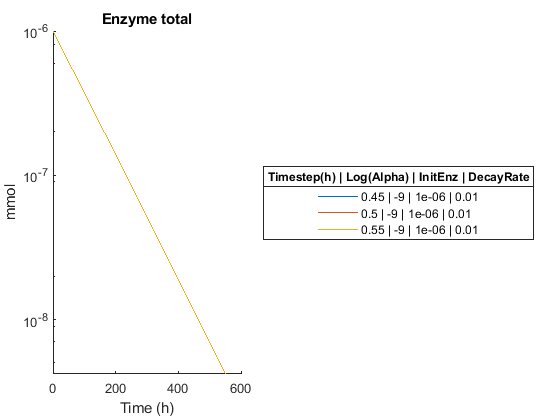

if ~exist('tsdat','var')
    load('timestep_sensitivity_2ddata.mat');
end
if ~exist('tsdat_full','var')
    tsdat_full = tsdat;
end

tsdat = tsdat_full;
%tsdat = tsdat(tsdat.alpha == alphas(1),:);
%tsdat = tsdat(tsdat.decayrate == 0.1,:);

[nrows,~] = size(tsdat);
colors = lines(nrows);
legendlocation = 'best';
legendlocation = 'eastoutside';
legendtitle = 'Timestep(h) | Log(Alpha) | InitEnz | DecayRate';
namefun = @(x) [num2str(tsdat.t{x}(2) / tsdat.timestep{x}(2)) ' | ' num2str(log(tsdat.alpha(x))) ' | ' num2str(tsdat.enz_total{x}(1)) ' | ' num2str(tsdat.decayrate(x))];

for i = 1:nrows
    tsdat.initenz(i) = tsdat.enz_total{i}(1);
    tsdat.initenz_log10(i) = log10(tsdat.enz_total{i}(1));
end

%tsdat = tsdat(tsdat.initenz == 1e-6,:);

[nrows,~] = size(tsdat);
colors = lines(nrows);

figure();
hold on;
for i = 1:nrows
    plot(tsdat.t{i},tsdat.enz_total{i},'color',colors(i,:),'DisplayName',namefun(i));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend('location',legendlocation);
title(leg,legendtitle);
xlabel('Time (h)');
ylabel('mmol');

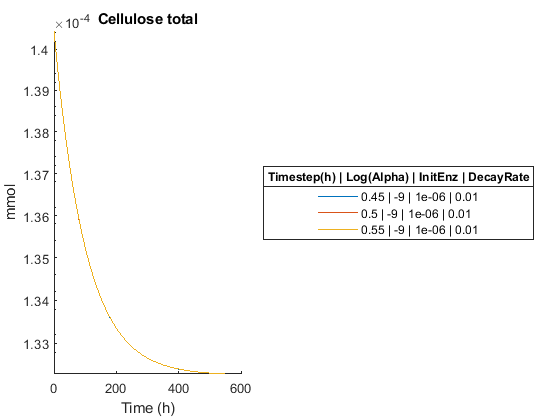

%ylim([1e-12 1e-3]);

figure();
hold on;
for i = 1:nrows
    plot(tsdat.t{i},tsdat.cellulose_total{i},'color',colors(i,:),'DisplayName',namefun(i));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend('location',legendlocation);
title(leg,legendtitle);
xlabel('Time (h)');
ylabel('mmol');

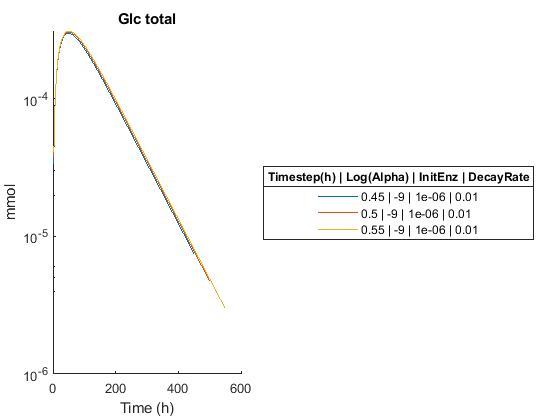

%ylim([1e-5 1e-3]);

figure();
hold on;
for i = 1:nrows
    plot(tsdat.t{i},tsdat.glc_total{i},'color',colors(i,:),'DisplayName',namefun(i));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend('location',legendlocation);
title(leg,legendtitle);
xlabel('Time (h)');
ylabel('mmol');

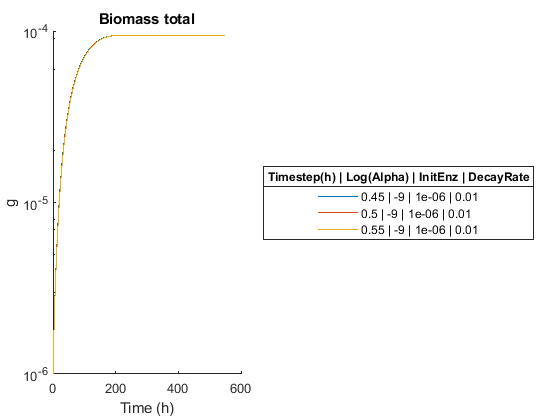

%ylim([1e-7 1e-1]);

figure();
hold on;
for i = 1:nrows
    plot(tsdat.t{i},tsdat.producer_total{i},'color',colors(i,:),'DisplayName',namefun(i));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend('location',legendlocation);
title(leg,legendtitle);
xlabel('Time (h)');
ylabel('g');

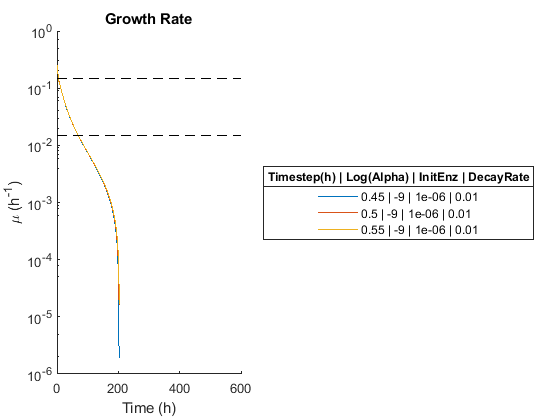

%ylim([1e-6 1e-2]);

figure();
hold on;
for i = 1:nrows
    plot(tsdat.t{i}(1:end-1),tsdat.producer_growthrate{i},'color',colors(i,:),'DisplayName',namefun(i));
end
plot(get(gca,'Xlim'),[.15 .15],'--k','HandleVisibility','off');
plot(get(gca,'Xlim'),[.015 .015],'--k','HandleVisibility','off');
set(gca,'Yscale','log');
title('Growth Rate');
leg = legend('location',legendlocation);
title(leg,legendtitle);
xlabel('Time (h)');
ylabel('\mu (h^-^1)');

hold off;